# **产生扫频信号**

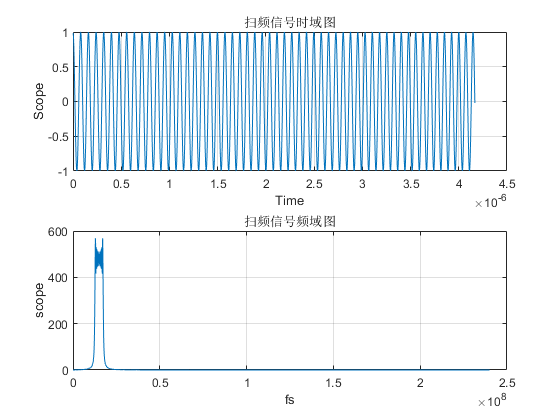

clear, close, clc
fs=480e6;%系统采样速率
T=20e-6;%所采样的时间
t = 1/fs:1/fs:T;
n=length(t);
f=(0:n/2)*(fs/n);%频率
f_low=12.5e6;f_hig=17.5e6;%上下边带
y=chirp(t,f_low,T,f_hig) ;%产生扫频信号
figure(1)
subplot (211)
plot(t(1:2000),y(1:2000));xlabel('Time'),ylabel('Scope'),title('扫频信号时域图'),grid on;
y_fft=abs(fft(y,length(y)));
subplot (212)
plot(f,y_fft(1:n/2+1)),xlabel('fs'),ylabel('scope'),grid on;title('扫频信号频域图')

###     可以从图中看出，我们在12.5MHz`～`17.5MHz产生的一段频率信号，此处扫频采用的事chirp产生扫频，原理如图所示：

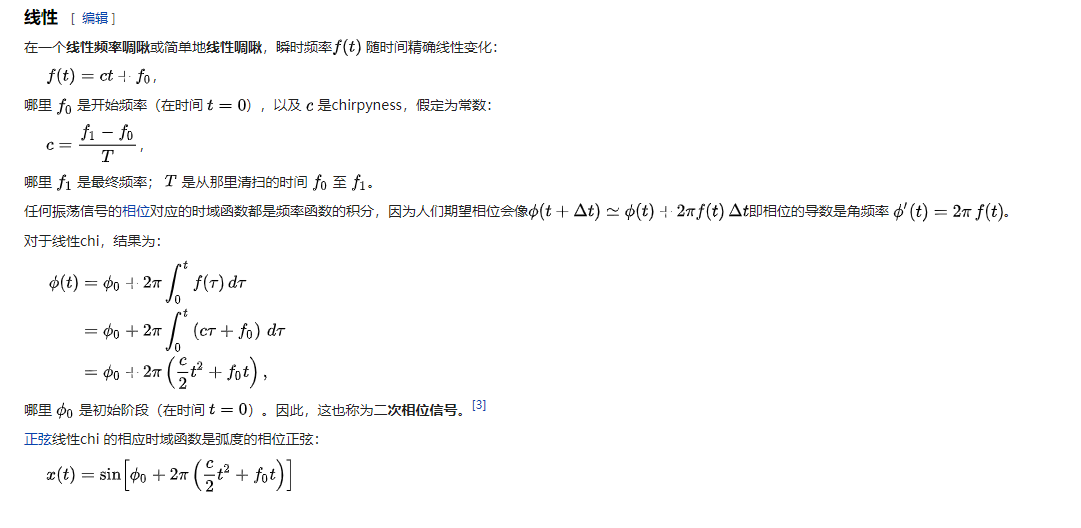

# 产生锯齿波信号

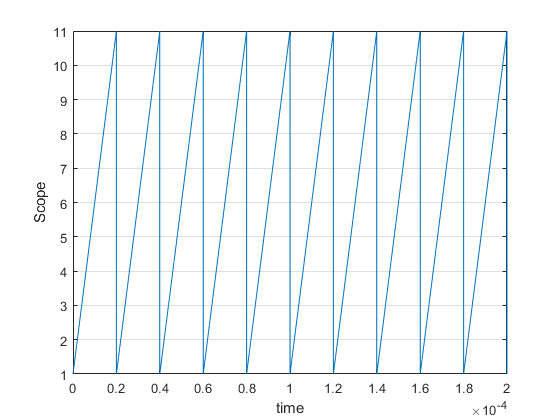

t_saw=1/fs:1/fs:T*10;%锯齿波产生的时间，因为频率和时间给出的信息其实都可以划在时间范围内，所以此处只采用了时间信息
y_Saw=sawtooth(2*pi*1/T*t_saw);%但是此处产生的信号范围在-1,1.所以对其进行变化。
y_Saw=y_Saw*5+6;
figure(2)
plot(t_saw,y_Saw),xlabel('time'),ylabel('Scope'),grid on;

###     为了直观理解三角波信号，此处我直接画了10个周期的信号

# 扫频信号与锯齿波相乘

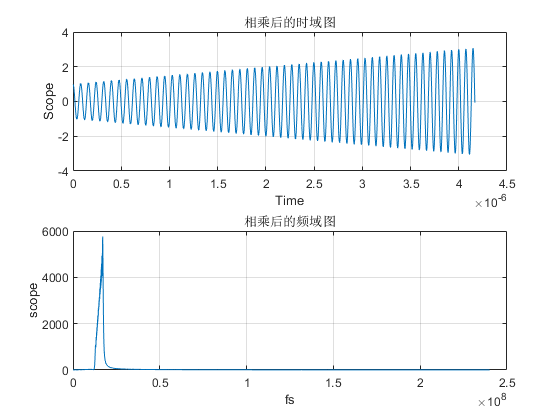

y_A=y_Saw(1:9600).*y;
y_Afft=abs(fft(y_A));
figure(3)
subplot (211)
plot(t(1:2000),y_A(1:2000));xlabel('Time'),ylabel('Scope'),grid on;title('相乘后的时域图')
subplot (212)
plot(f,y_Afft(1:n/2+1)),xlabel('fs'),ylabel('scope'),grid on;title('相乘后的频域图')

###     锯齿波信号与原始扫频信号相乘之后可以看出原始的扫频信号出现了一定的斜率，这是因为锯齿波的性质造成的，锯齿波的频谱图。

# 进行60MHz采样

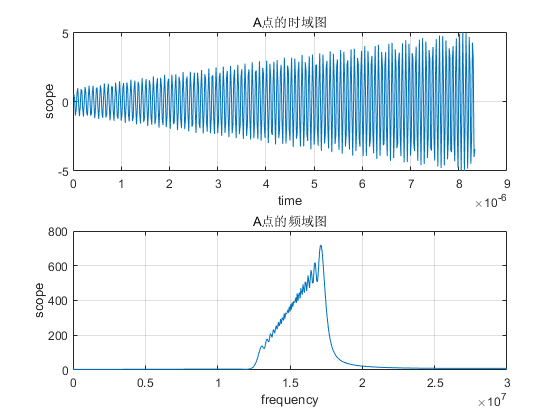

f_A=60e6;%60MHz的采样
t_A=1/f_A:1/f_A:T;%时间
n_A=length(t_A);
y_resamp=resample(y_A,1,8);
t_resamp=(1:length(y_resamp))*8/(fs);
figure(4)
y_reFFt=abs(fft(y_resamp));
fs_resamp=(1:n_A/2)*(f_A/n_A);
subplot 211 
plot(t_resamp(1:500),y_resamp(1:500)),xlabel('time'),ylabel('scope'),title('A点的时域图'),grid on ;
subplot 212
plot(fs_resamp,y_reFFt(1:600)),xlabel('frequency'),ylabel('scope'),title('A点的频域图'), grid on;

###     对信号进行60MHz采样，此处采用的事resample函数，可以看出进行频率重采样后，信号变得稀疏。

# B点进行滤波

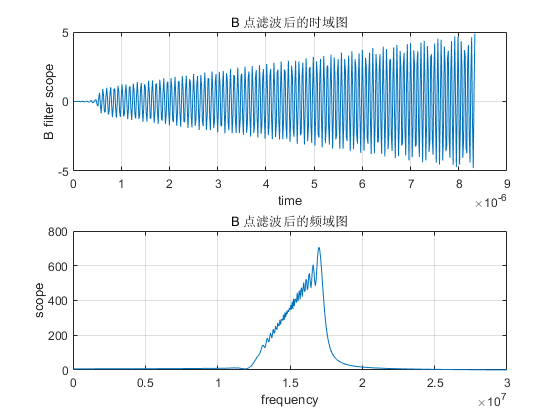

[a,b]=tf(bandpas_1);
B_filter=filter(a,b,y_resamp);
B_filterfft=abs(fft(B_filter));
figure(5)
subplot 211
plot(t_resamp(1:500),B_filter(1:500)),xlabel('time'),ylabel('B filter scope'),title('B 点滤波后的时域图'),grid on ;
subplot 212
plot(fs_resamp,B_filterfft(1:600)),xlabel('frequency'),ylabel('scope'),title('B 点滤波后的频域图'), grid on;

###     此处利用matlab自带的滤波器设计FIR带通滤波器，信号经过滤波没有多大变化只有在刚开始的一段信号被滤掉了，因此猜测在刚开始有一些低频或高频信号。

# B点进行3倍抽取

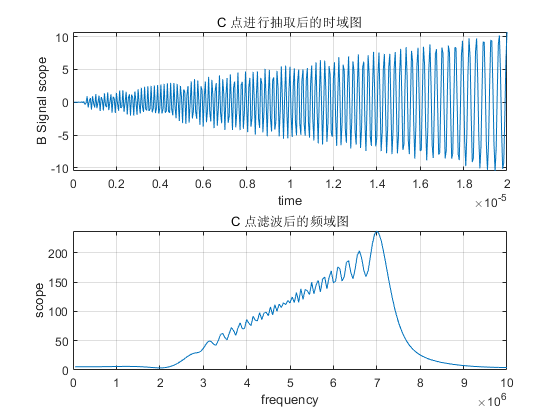

B_signal=downsample(B_filter,3);
B_signalfft=abs(fft(B_signal));
f_B=f_A/3;%进行抽取频率变化
t_B=1/f_B:1/f_B:T;%B 处的时间
n_B=length(t_B);
fs_B=(1:n_B/2)*(f_B/n_B);
figure(6)
subplot 211
plot(t_B,B_signal),xlabel('time'),ylabel('B Signal scope'),title('C 点进行抽取后的时域图'), grid on ;
subplot 212
plot(fs_B,B_signalfft(201:400)),xlabel('frequency'),ylabel('scope'),title('C 点滤波后的频域图'), grid on;

###     对信号进行3倍抽取后可以看出在fs范围内信号带宽变宽，同时需要注意的还有横坐标相应的变换。

# 第四步，先进行插值，然后进行滤波

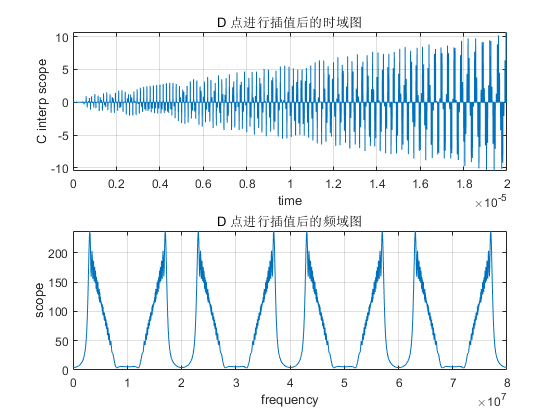

C_interp=upsample(B_signal,8);
C_interpfft=abs(fft(C_interp));
f_C=f_B*8;%进行抽取频率变化
t_C=1/f_C:1/f_C:T;%B 处的时间
n_C=length(t_C);
fs_C=(1:n_C/2)*(f_C/n_C);
figure(7)
subplot 211
plot(t_C,C_interp),xlabel('time'),ylabel('C interp scope'),title('D 点进行插值后的时域图'), grid on ;
subplot 212
plot(fs_C,C_interpfft(1601:3200)),xlabel('frequency'),ylabel('scope'),title('D 点进行插值后的频域图'), grid on;

###     对信号进行插值，可以看出在时域信号补了许多零，因此在频域的信号产生许多镜像，我们要的到期望的信号必须对插值后的信号进行滤波。

### E点进行带通滤波

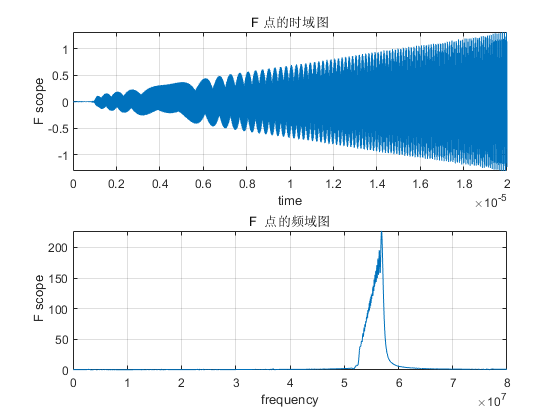

[c,d]=tf(bandpass_2);
E_filter=filter(c,d,C_interp);
E_filterfft=abs(fft(E_filter));
figure(8)
subplot 211
plot(t_C,E_filter),xlabel('time'),ylabel('F scope'),title('F 点的时域图'), grid on ;
subplot 212
plot(fs_C,E_filterfft(1:1600)),xlabel('frequency'),ylabel(' F scope'),title('F  点的频域图'), grid on;

### **最终得到了滤波后的信号，**

### **    本节信号的难点在于滤波器的设计，横坐标相应的变化，有时候横坐标的点选取不好会出现很多意想不到的图。因此要将横坐标充分理解。我在此每次都对横坐标进行相应的变换，总的时间不变。采样时间根据他的采样频率变换。**